# Tutorial 1: Statistics Module

In this tutorial you will set up your first linear model with BrainStat. To this end, we will load some sample data from the MICS dataset. But before we get started, please note that this tutorial requires that you have BrainStat and all its dependencies installed. For more details see our installation guide. 

## A simple fixed effects model

Lets have a look at the cortical thickness data and the demographics data. Note that we've defined a function, `pretty_plot`, at the end of this file to make the plots a little prettier when they're embedded inside live scripts. If you run this tutorial outside of a live script you'll want to comment out the `pretty_plot` lines.

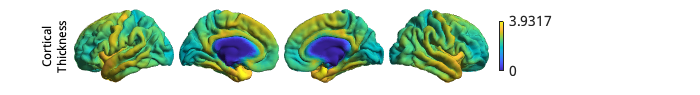

[cortical_thickness, demographics] = fetch_mics_data();
[surf_left, surf_right] = fetch_template_surface('fsaverage5');

obj = plot_hemispheres(...
    mean(cortical_thickness)',  ...
    {surf_left, surf_right}, ...
    'labeltext', {{'Cortical', 'Thickness'}} ...
); 
pretty_plot(obj);

disp(demographics)

     SUB_ID     VISIT    AGE_AT_SCAN     SEX 
    ________    _____    ___________    _____

    {'e873'}      1          31         {'M'}
    {'e000'}      1          36         {'M'}
    {'04a1'}      1          25         {'M'}
    {'d7c4'}      1          22         {'F'}
    {'aca8'}      1          23         {'M'}
    {'33a4'}      1          22         {'M'}
    {'522a'}      1          41         {'M'}
    {'41e2'}      1          29         {'M'}
    {'f257'}      1          30         {'F'}
    {'de11'}      1          36         {'M'}
    {'2423'}      1          26         {'F'}
    {'4209'}      1          27         {'F'}
    {'c040'}      1          24         {'M'}
    {'b979'}      1          35         {'M'}
    {'29b7'}      1          23         {'F'}
    {'9ce7'}      1          28         {'M'}
    {'b867'}      1          19    

Demographics contains four variables: a subject ID, a visit number (some subjects visited multiple times), their age at the time of scanning and their sex. Next, we will assess whether a subject's age is related to their cortical thickness. To this end we can create a linear model with BrainStat. For our first model, we will only consider the effect of age, i.e. we will disregard the effect of sex and that some subjects appear twice.

term_age = FixedEffect(demographics.AGE_AT_SCAN, 'Age');
model = term_age;
disp(model)

  71×2 FixedEffect array with properties:

     names: ["intercept"    "Age"]
    matrix: [71×2 double]



As you can see, model contains two properties: the names of each variable and a matrix containing the effects in a observation-by-variable matrix. As you can see, an intercept is included in the model by default.

Next, we must define a contrast in observations (here: age). With the model, contrast, and cortical thickness data, we can then assess whether there is an effect of age on cortical thickness. 

contrast_age = demographics.AGE_AT_SCAN;
mask = fetch_mask('fsaverage5');

BrainStatModel = SLM( ...
   model, ...
   contrast_age, ...
   'surf', 'fsaverage5', ...
   'correction', {'rft', 'fdr'}, ...
   'cluster_threshold', 0.05, ... % We use a liberal threshold for the tutorial.
   'mask', mask);
BrainStatModel.fit(cortical_thickness);


We can access the outcome of this model through its properties. Lets plot the t-values, as well as the peak and cluster p-values derived from a random field theory correction. We've defined a function for slm results at the end of this file as we'll be doing this a lot. 

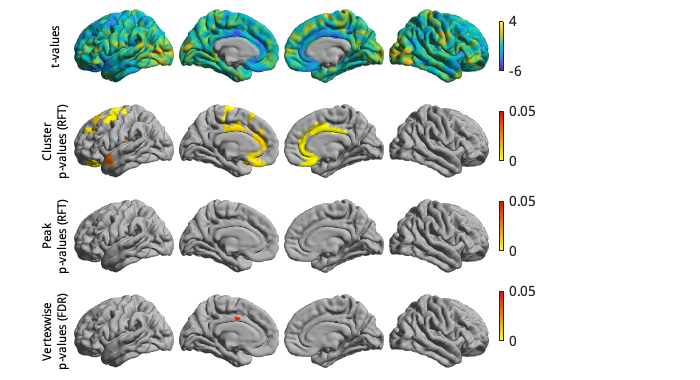

plot_slm(BrainStatModel, {surf_left, surf_right}, mask, true, true);

Only clusters are significant, and not peaks. This suggests that the age effect covers large regions, rather than local foci. Furthermore, at the vertexwise level we only find a small group of significant vertices in the medial cingulate cortices. Lets have a closer look at the clusters and their peaks. The data on clusters are stored in tables inside BrainStatModel.P.clus and information on the peaks is stored in BrainStatModel.P.peak. If a two-tailed test is run (BrainStat defaults to two-tailed), a table is returned for each tail. The first table uses the contrast as provided, the second table uses the inverse contrast. If a one-tailed test is performed, then only a single table is returned. Lets print the first 15 rows of the inverted contrast cluster table. 

disp(BrainStatModel.P.clus{2}(1:15, :))

    clusid    nverts    resels        P     
    ______    ______    ______    __________

       1       373       17.53    1.0676e-05
       2       192      9.3448    0.00094661
       3       186      8.4368     0.0022178
       4       166      8.1701     0.0028677
       5       159      7.9658     0.0034986
       6       138      7.7429     0.0043558
       7       169      6.6741      0.012837
       8       105      5.7065      0.035621
       9       121      5.6975      0.035968
      10        89      4.6876       0.10765
      11       103      4.3844       0.14967
      12        80      4.0855       0.20627
      13        85      3.8645       0.26018
      14        64       3.414       0.40776
      15        70      3.1303       0.52674



Here, we see that cluster 1 contains 373 vertices. Clusters are sorted by p-value; later clusters will generally be smaller and have higher p-values. Lets now have a look at the peaks within these clusters. 

disp(BrainStatModel.P.peak{2}(1:15, :))

      t       vertid    clusid       P               yeo7        
    ______    ______    ______    ________    ___________________

    4.9121    18720       11      0.027587    "Ventral Attention"
    4.7864     5430       15      0.042049    "Default"          
    4.6904     8454        4      0.057845    "Ventral Attention"
    4.6701    11387       13      0.061742    "Ventral Attention"
    4.3972    19629        1       0.14893    "Frontoparietal"   
    4.3054    10524        1       0.19871    "Frontoparietal"   
    4.1963     2169        6       0.27804    "Default"          
    4.1855     9060        6       0.28756    "Default"          
     4.003    12603       12         0.497    "Default"          
    3.8905     4866        3       0.69079    "Limbic"           
    3.8893    19000        1       0.

Within cluster 1, we are able to detect several peaks. The peak with the highest t-statistic (t=4.3972) occurs at vertex 19629, which is inside the frontoparietal network as defined by the Yeo-7 networks. Note that the Yeo network membership is only provided if the surface is specified as a template name as we did here. For custom surfaces, or pre-loaded surfaces (as we will use below) this column is omitted. 

### One-tailed Test

One-tailed tests may be useful when your hypothesis states that the effect will be in a particular direction. By default BrainStat uses a two-tailed test. If you want to get a one-tailed test, simply specify it in the SLM model initialization with `'two_tailed', false`. Note that the one-tailed test will test for the significance of positive t-values. If you want to test for the significance of negative t-values, simply change the sign of the contrast. We may hypothesize based on prior research that cortical thickness decreases with age, so we could specify this as follows. Note the minus in front of `contrast_age` to test for decreasing thickness with age.

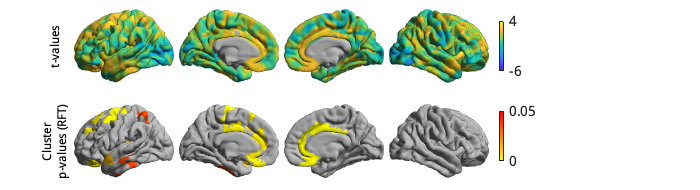

surface = fetch_template_surface('fsaverage5', 'join', true);
BrainStatModel_onetailed = SLM(...
    model, ...
    -contrast_age, ...
    'correction', 'rft', ...
    'surf', surface, ...
    'mask', mask, ...
    'cluster_threshold', 0.05, ...
    'two_tailed', false ...
);
BrainStatModel_onetailed.fit(cortical_thickness);

plot_slm(BrainStatModel_onetailed, {surf_left, surf_right}, mask);

Notice the additional clusters that we find in the lateral temporal lobe and the parietal lobe when using a one-tailed test. The peak p-values (not shown) are wholly non-significant again. 

## Interaction effects models

So far we've only considered the effect of age on cortical thickness. However, we've ignored another important variable: sex. Sex may have an effect on cortical thickness as well, and so we should correct for this in our models. First lets set up a new model which includes both the effect of sex, as well as an interaction between age and sex. Additional effects can be added by addition, and interactions are created by multiplication.

term_sex = FixedEffect(demographics.SEX);
model_interaction = term_age + term_sex + term_age * term_sex;

 Next we will rerun the model and see if our results change. 

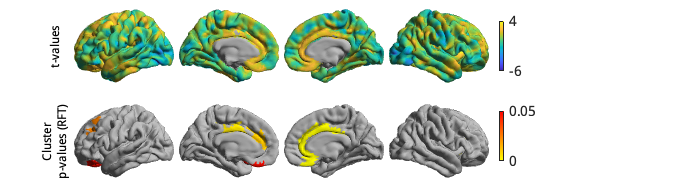

BrainStatModel_interaction = SLM( ...
   model_interaction, ...
   -contrast_age, ...
   'surf', surface, ...
   'correction', 'rft', ...
   'two_tailed', false, ...
   'cluster_threshold', 0.05, ...
   'mask', mask);
BrainStatModel_interaction.fit(cortical_thickness);

plot_slm(BrainStatModel_interaction, {surf_left, surf_right}, mask);

It seems like most of our significant clusters disappear once we account for the effects of sex on cortical thickness. 

Instead of looking at the effects of age, we could also look at the effects of sex simply by changing the contrast. Lets create a new contrast to assess cortical thickness changes across sex. Recall that the model contains each of the effects. We can simply use the dummy variables for male (M) and female (F) to create the new contrast.

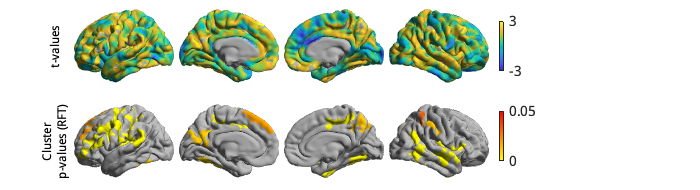

contrast_sex = model_interaction.M - model_interaction.F;

BrainStatModel_sex = SLM( ...
   model_interaction, ...
   contrast_sex, ...
   'surf', surface, ...
   'correction', 'rft', ...
   'cluster_threshold', 0.05, ...
   'mask', mask);
BrainStatModel_sex.fit(cortical_thickness);

obj = plot_slm(BrainStatModel_sex, {surf_left, surf_right}, mask);
obj.colorlimits([-3, 3; 0, 0.05]);

Due to how we set up our contrast (male-female), positive t-values denote higher cortical thickness in men. The significant clusters all appear within with positive t-values indicating that overall men have a thicker cortex than women. 

We could also look at whether the cortex of men and women changes differently with age by comparing their interaction effects. 

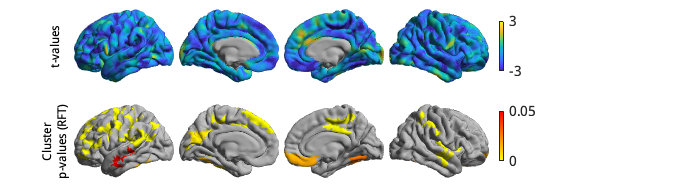

contrast_sex_int = (model_interaction.M .* model_interaction.Age) - ...
                   (model_interaction.F .* model_interaction.Age);

BrainStatModel_sex_int = SLM( ...
   model_interaction, ...
   contrast_sex_int, ...
   'surf', surface, ...
   'correction', 'rft', ...
   'cluster_threshold', 0.05, ...
   'mask', mask);
BrainStatModel_sex_int.fit(cortical_thickness);

obj = plot_slm(BrainStatModel_sex_int, {surf_left, surf_right}, mask);
obj.colorlimits([-3, 3; 0, 0.05]);

Indeed, it appears that the interaction effect between sex and age is quite different across men and women, with stronger effects occuring in women. 

## Mixed Effects Models (DEFUNCT!)

So far, we've considered multiple visits of the same subject as two separate, independent measurements. Clearly, however, such measurements are not independent of each other. To account for this, we could add subject ID as a random effect. Lets do this and test the effect of age on cortical thickness again.

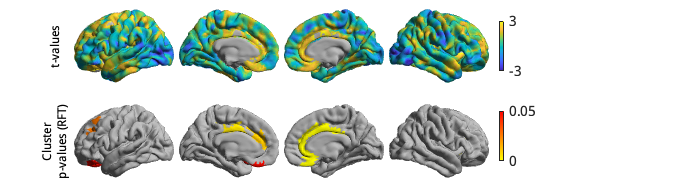

term_subject = MixedEffect(demographics.SUB_ID);
model_mixed = term_age + term_sex + term_age * term_sex + term_subject;

BrainStatModel_mixed = SLM( ...
   model_mixed, ...
   -contrast_age, ...
   'surf', surface, ...
   'correction', 'rft', ...
   'cluster_threshold', 0.05, ...
   'two_tailed', false, ...
   'mask', mask);
BrainStatModel_mixed.fit(cortical_thickness);

obj = plot_slm(BrainStatModel_mixed, {surf_left, surf_right}, mask);
obj.colorlimits([-3, 3; 0, 0.05]);

ADD MIXED EFFECTS ONCE SITE 2 DATA IS INCLUDED!

It appears that, after correction for site as a random variable, the significant results are far more localized. That concludes the basic usage of the BrainStat for statistical models. In the next tutorial we'll show you how to use the context decoding module.

Below are the support functions used in this live script. 

function pretty_plot(obj)
    % Makes the BrainSpace plots prettier inside live scripts. 
    obj.handles.figure.Units = 'pixels';
    set(obj.handles.axes, 'Units', 'pixels')
    set(obj.handles.colorbar, 'Units', 'pixels');
    obj.handles.figure.Position = [1, 1, 700, size(obj.data, 2) * 95];
    set(obj.handles.text, 'FontSize', 12);
    
    for jj = 1:size(obj.data, 2) % variates
        obj.handles.colorbar(jj).Position = [...
            500, ...
            30 + (size(obj.data, 2) * 95) - 10 - jj*90, ...
            5, ...
            50];
        for ii = 1:4 % views
            obj.handles.axes(jj, ii).Position = [...
                75 + (ii-1)*105, ...
                (size(obj.data, 2) * 95) - jj*95, ...
                100, ...
                100];
        end
    end
end

function obj = plot_slm(slm, surfaces, mask, plot_peak, plot_fdr)
arguments
    slm
    surfaces
    mask
    plot_peak (1,1) logical = false
    plot_fdr (1,1) logical = false
end

to_plot = [slm.t(:), slm.P.pval.C(:)];
labels = {'t-values', {'Cluster', 'p-values (RFT)'}};
colormaps = {[parula; .7 .7 .7];
              [flipud(autumn); .7 .7 .7]};
colorlimits = [-6, 4; 0, 0.05];

if plot_peak
    to_plot = [to_plot, slm.P.pval.P(:)];
    labels = [labels, {{'Peak', 'p-values (RFT)'}}];
    colormaps = [colormaps; {[flipud(autumn); .7 .7 .7]}];
    colorlimits = [colorlimits; 0, 0.05];
end

if plot_fdr
    to_plot = [to_plot, slm.Q(:)];
    labels = [labels, {{'Vertexwise', 'p-values (FDR)'}}];
    colormaps = [colormaps; {[flipud(autumn); .7 .7 .7]}];
    colorlimits = [colorlimits; 0, 0.05];
end

to_plot(~mask, :) = inf;

obj = plot_hemispheres(...
    to_plot,  ...
    {surfaces{1}, surfaces{2}}, ...
    'labeltext', labels ...
);

obj.colormaps(colormaps);
obj.colorlimits(colorlimits);
pretty_plot(obj);
end